% cleaning
clc
clear

% importing data
df1=readtable("..\data\experimental-data-1.csv")

df1 = 10×4 table
    dimension    value    uncertainty      uom  
    _________    _____    ___________    _______

     {'s1'}      1.775       0.001       {'MTR'}
     {'s2'}      1.105       0.001       {'MTR'}
     {'s3'}      0.425       0.001       {'MTR'}
     {'su'}      0.539       0.001       {'MTR'}
     {'m0'}       9.85        0.01       {'GRM'}
     {'m1'}      10.23        0.01       {'GRM'}
     {'m2'}       20.1        0.01       {'GRM'}
     {'m3'}      30.33        0.01       {'GRM'}
     {'m4'}      40.21        0.01       {'GRM'}
     {'M' }      296.5         0.1       {'GRM'}


df2=readtable("..\data\experimental-data-3.csv")

df2 = 100×5 table
    index     mass      t1      uncertainty      uom  
    _____    ______    _____    ___________    _______

      1      {'m0'}    1.983       0.001       {'SEC'}
      2      {'m0'}    1.983       0.001       {'SEC'}
      3      {'m0'}    1.981       0.001       {'SEC'}
      4      {'m0'}    1.989       0.001       {'SEC'}
      5      {'m0'}     1.99       0.001       {'SEC'}
      6      {'m0'}    1.984       0.001       {'SEC'}
      7      {'m0'}    1.988       0.001       {'SEC'}
      8      {'m0'}    1.991       0.001       {'SEC'}
      9      {'m0'}    1.984       0.001       {'SEC'}
     10      {'m0'}     1.99       0.001       {'SEC'}
     11      {'m0'}     1.99       0.001       {'SEC'}
     12      {'m0'}    1.993       0.001       {'SEC'}
     13      {'m0'}    1.987       0.001 

tools=readtable("..\data\tools.csv")

tools = 3×3 table
         tool         uncertainty      uom  
    ______________    ___________    _______

    {'Bilancia'  }        0.01       {'GRM'}
    {'Metro'     }       0.001       {'MTR'}
    {'Cronometro'}       0.001       {'SEC'}


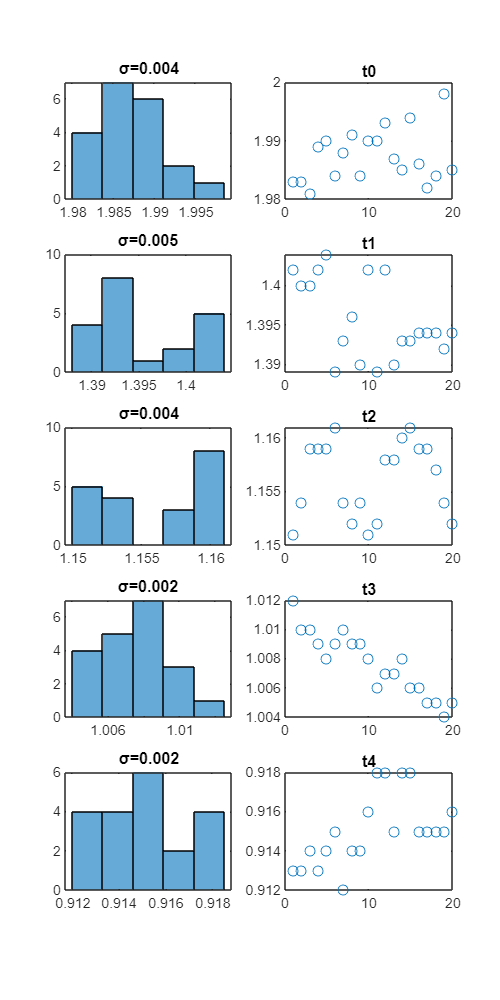

% defining variables
t0=df2.t1(1:20,:);
t1=df2.t1(21:40,:);
t2=df2.t1(41:60,:);
t3=df2.t1(61:80,:);
t4=df2.t1(81:100,:);

s1=df1.value(1);
s2=df1.value(2);
ds=df1.uncertainty(1);
dm=df1.uncertainty(5)./1000; %kg

% uncomment to aproximate t
% dt=0.01;
% t0=round(t0,2);
% t1=round(t1,2);
% t2=round(t2,2);
% t3=round(t3,2);
% t4=round(t4,2);

% average t
tm0=mean(t0);
tm1=mean(t1);
tm2=mean(t2);
tm3=mean(t3);
tm4=mean(t4);

% creating array for t
tm=[tm0,tm1,tm2,tm3,tm4];
lt=length(tm);

% space
s=s1-s2;

% gravitational acceleration
g=9.8;
dg=0.1;

% masses in g
m=zeros(lt,1);
m(1)=df1.value(5);
m(2)=m(1)+df1.value(6);
m(3)=m(1)+df1.value(7);
m(4)=m(1)+df1.value(8);
m(5)=m(1)+df1.value(9);

% masses in kg
m=m/1000;

% standard deviation t
std0=round(std(t0),3);
std1=round(std(t1),3);
std2=round(std(t2),3);
std3=round(std(t3),3);
std4=round(std(t4),3);
dt=[std0,std1,std2,std3,std4];

% creating empty array
a=zeros(lt,1);      % acceleration
da=zeros(lt,1);     % delta a
rea=zeros(lt,1);    % relative error a
cfra=zeros(lt,1);   % position first significant digit da
cfrf=zeros(lt,1);   % position first significant digit df
f=zeros(lt,1);      % force
df=zeros(lt,1);     % delta F
ref=zeros(lt,1);    % relative error force
mc=zeros(lt,1);     % mass of the cart
dmc=zeros(lt,1);    % error mass cart
remc=zeros(lt,1);   % rleative error mass cart
cfrmc=zeros(lt,1);  % position first significant digit dmc
as=zeros(lt,1);     % acceleration significant digits
fs=zeros(lt,1);     % force significant digits
mcs=zeros(lt,1);    % mass cart significant digits
uoma=string(zeros(lt,1));   % uom acceleration
uomf=string(zeros(lt,1));   % uom force
uommc=string(zeros(lt,1));  % uom mass cart

% core
for i=1:lt

    % acceleration
    a(i)=(2.*s)./(tm(i))^2;

    % force
    f(i)=m(i).*(g-a(i));
    
    % mass of cart
    mc(i)=m(i).*((g./a(i))-1);

    % propagation of error acceleration
    da(i)=(2.*ds+((4.*s.*dt(i))/(tm(i))))./(tm(i).^2);
    cfra(i)=-floor(log10(da(i)));   % position first significant digit a
    da(i)=round(da(i),cfra(i));     % round da
    a(i)=round(a(i),cfra(i));       %round acceleration
    
    % propagation of error force
    df(i)=((g-a(i))*2*dm)+(m(i)*dg)+(m(i)*((2.*ds+((4.*s.*dt(i))/(tm(i))))./(tm(i).^2)));
    cfrf(i)=-floor(log10(df(i)));   % position first significant digit f
    df(i)=round(df(i),cfrf(i));     % round df
    f(i)=round(f(i),cfrf(i));       % round f
    
    % propagation of error mass cart
    dmc(i)=((g/(a(i))-1)*2*dm)+((m(i)*dg)/a(i))+(((m(i)*g)/(a(i)^2))*(2.*ds+((4.*s.*dt(i))/(tm(i))))./(tm(i).^2));
    cfrmc(i)=-floor(log10(dmc(i)));     % position first significant digit dmc
    dmc(i)=round(dmc(i),cfrmc(i));      % round dmc
    mc(i)=round(mc(i),cfrmc(i));        % round f

    % relative error
    rea(i)=round((da(i)./a(i))*100,2);        % relative error a
    ref(i)=round((df(i)./f(i))*100,2);        % relative error f
    remc(i)=round((dmc(i)./mc(i))*100,2);     % relative error mc
    
end

% plotting

% number of bins
nb=5;

% full grid
fg=figure;
subplot(5,2,1)
histogram(t0,nb)
title(strcat('\sigma=',string(std0)))
subplot(5,2,2)
plot(1:20,t0,'o')
title('t0')
subplot(5,2,3)
histogram(t1,nb)
title(strcat('\sigma=',string(std1)))
subplot(5,2,4)
plot(1:20,t1,'o')
title('t1')
subplot(5,2,5)
histogram(t2,nb)
title(strcat('\sigma=',string(std2)))
subplot(5,2,6)
plot(1:20,t2,'o')
title('t2')
subplot(5,2,7)
histogram(t3,nb)
title(strcat('\sigma=',string(std3)))
subplot(5,2,8)
plot(1:20,t3,'o')
title('t3')
subplot(5,2,9)
histogram(t4,nb)
title(strcat('\sigma=',string(std4)))
subplot(5,2,10)
plot(1:20,t4,'o')
title('t4')
fg.Position=[10 10 800 1600]; % [left bottom width height]

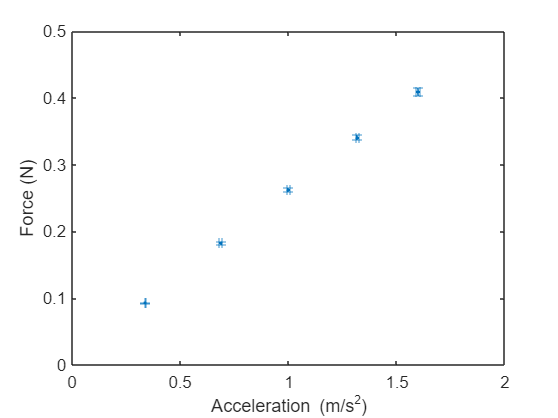


% scatterplot F-a
scatter=figure;
errorbar(a,f,df,df,da,da,'.')
xlabel('Acceleration (m/s^2)')
ylabel('Force (N)')
xlim([0,2])
ylim([0,0.5])


% visualize force array
force=horzcat(f,df,ref)

force =     0.0930    0.0010    1.0800
    0.1830    0.0020    1.0900
    0.2630    0.0030    1.1400
    0.3410    0.0040    1.1700
    0.4100    0.0060    1.4600



% visualize acceleration array
acceleration=horzcat(a,da,rea)

acceleration =     0.3390    0.0020    0.5900
    0.6880    0.0060    0.8700
    1.0020    0.0080    0.8000
    1.3200    0.0070    0.5300
    1.6000    0.0090    0.5600



% kg2g
mcm=mean(mc)*1000

mcm = 263.6000

mc=mc*1000;
dmc=dmc*1000;

% visualize mass of cart array
masscart=horzcat(mc,dmc,remc)

masscart =   275.0000    5.0000    1.8200
  266.0000    6.0000    2.2600
  263.0000    6.0000    2.2800
  258.0000    5.0000    1.9400
  256.0000    5.0000    1.9500



% significant digits
for i=1:lt
    as(i)=sprintf(strcat('%.',string(cfra(i)),'f'),a(i));
    fs(i)=sprintf(strcat('%.',string(cfrf(i)),'f'),f(i));
    mcs(i)=sprintf(strcat('%.',string(cfrmc(i)),'f'),mc(i));
end

% converting array num to string
a=string(a);
da=string(da);
rea=string(rea);
f=string(f);
df=string(df);
ref=string(ref);
mc=string(mc);
dmc=string(dmc);
remc=string(remc);

% substituting values
for i=1:lt
    a(i)=as(i);
    f(i)=fs(i);
    mc(i)=mcs(i);
    rea(i)=sprintf('%.2f',rea(i));
    ref(i)=sprintf('%.2f',ref(i));
    remc(i)=sprintf('%.2f',remc(i));
    uoma(i)='MSK';
    uomf(i)='NEW';
    uommc(i)='GRM';
end

% creating output array
acceleration=horzcat(a,da,uoma,rea)

acceleration = 5×4 string array
    "0.339"    "0.002"    "MSK"    "0.59"
    "0.688"    "0.006"    "MSK"    "0.87"
    "1.002"    "0.008"    "MSK"    "0.80"
    "1.32"     "0.007"    "MSK"    "0.53"
    "1.6"      "0.009"    "MSK"    "0.56"


force=horzcat(f,df,uomf,ref)

force = 5×4 string array
    "0.093"    "0.001"    "NEW"    "1.08"
    "0.183"    "0.002"    "NEW"    "1.09"
    "0.263"    "0.003"    "NEW"    "1.14"
    "0.341"    "0.004"    "NEW"    "1.17"
    "0.41"     "0.006"    "NEW"    "1.46"


masscart=horzcat(mc,dmc,uommc,remc)

masscart = 5×4 string array
    "275"    "5"    "GRM"    "1.82"
    "266"    "6"    "GRM"    "2.26"
    "263"    "6"    "GRM"    "2.28"
    "258"    "5"    "GRM"    "1.94"
    "256"    "5"    "GRM"    "1.95"


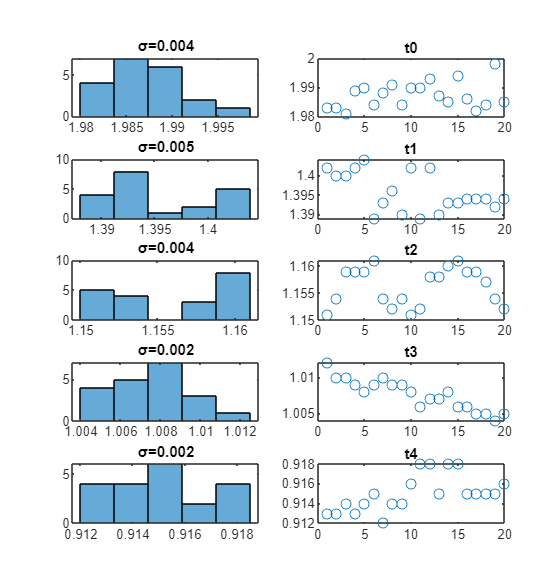

% exporting csv
writetable(array2table(acceleration,'VariableNames',{'acceleration','uncertainty','uom','relative_error'}),'..\data\output-data-1.csv','Delimiter',',','Encoding','UTF-8')
writetable(array2table(force,'VariableNames',{'force','uncertainty','uom','relative_error'}),'..\data\output-data-2.csv','Delimiter',',','Encoding','UTF-8')
writetable(array2table(masscart,'VariableNames',{'mass','uncertainty','uom','relative_error'}),'..\data\output-data-3.csv','Delimiter',',','Encoding','UTF-8')

% exporting img
saveas(fg,'..\img\img-1.png');

saveas(scatter,'..\img\img-2.png');


% exporting mlx2m
mlxloc = fullfile(pwd,'livescript.mlx');
fileout = 'script.m';
matlab.internal.liveeditor.openAndConvert(mlxloc,fileout);